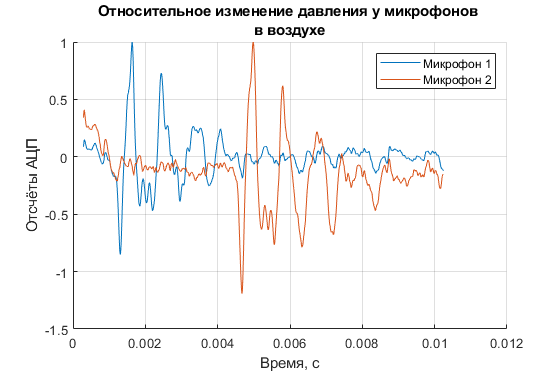

%Очистка
close all;
clear valuables;

%Импорт данных
airRaw = importdata("air.txt");
breathRaw = importdata("breath.txt");
totalTime = importdata("totalTime.txt");
samplingFrequency = importdata("samplingFrequency.txt");
dt = 1/samplingFrequency;
ttRaw = (linspace(0, totalTime, totalTime/dt))';
T = importdata("temperature.txt");
wO2 = importdata("volumeFractionWater.txt");

%Нормировка
windowSize = 5;
b = (1/windowSize) * ones(1, windowSize);
a=1;

airFiltered = filter(b,a,airRaw());
breathFiltered = filter(b,a, breathRaw());

start = 30;

airFiltered = airFiltered(start:end, :);
breathFiltered = breathFiltered(start:end, :);
tt = ttRaw(start:end);

cAir = polyfit(tt, airFiltered(:, 1), 3);
cBreath = polyfit(tt, breathFiltered(:, 1), 3);

air = airFiltered - polyval(cAir, tt);
airNorm = air ./max(air);

breath = breathFiltered - polyval(cBreath, tt);
breathNorm = breath ./max(breath);

%Давление 1

f1 = figure();
hold on;
grid on;
title({'Относительное изменение давления у микрофонов ', 'в воздухе'});
ylabel('Отсчёты АЦП');
xlabel('Время, с');

plot(tt, airNorm(:, 1), 'DisplayName', "Микрофон 1");

plot(tt, airNorm(:, 2), 'DisplayName', "Микрофон 2");

legend('Location', 'northeast');
saveas(f1, "Давление 1.png");
set(f1, 'Visible', 'on');

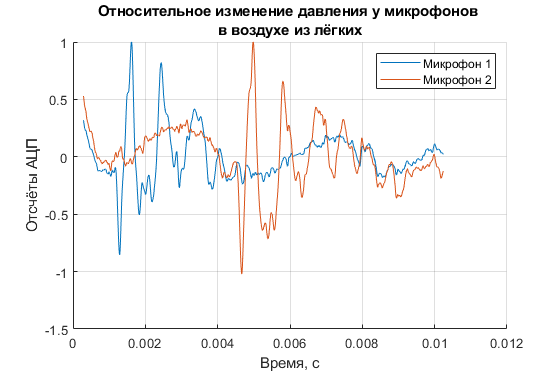


%Давление 2

f2 = figure();
hold on;
grid on;
title({'Относительное изменение давления у микрофонов ', 'в воздухе из лёгких'});
ylabel('Отсчёты АЦП');
xlabel('Время, с');

plot(tt, breathNorm(:, 1), 'DisplayName', "Микрофон 1");
plot(tt, breathNorm(:, 2), 'DisplayName', "Микрофон 2");
legend('Location', 'northeast');
saveas(f2, "Давление 2.png");
set(f2, 'Visible', 'on');

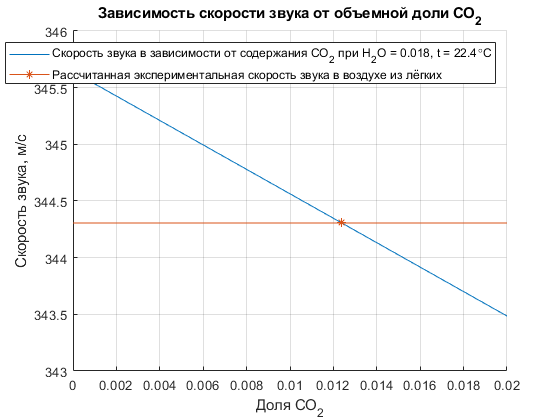


%Скорость звука 1

[M01, I01] = max(airNorm(:,1));
T01 = tt(I01);
[M02, I02] = max(airNorm(:,2));
T02 = tt(I02);
L = 1.158;
dT0 = T02 -T01;

V0 = L/(dT0);
dV0 = sqrt((0.001/1.158)^2 + ((dt/(T2 - T1))^2))*V0;
Ev0 = dV0/V0*100;

%Скорость звука 2

[M1, I1] = max(breathNorm(:,1));
T1 = tt(I1);
[M2, I2] = max(breathNorm(:,2));
T2 = tt(I2);
L = 1.158;
dT = T2 - T1;

V = L/(T2 - T1);
dV = sqrt((0.001/1.158)^2 + ((dt/(T2 - T1))^2))*V;
Ev = dV/V*100;

%ТАБЛИЧНЫЕ ДАННЫЕ ДЛЯ ГРАФИКА СКОРОСТИ ВЫДЫХАНИЯ
%НАЙДЕМ ТОЧКИ ДЛЯ ГРАФИКА ЗАВИСИМОСТИ 
%ПРИ ОБЪЕМНОЙ ДОЛЕ ВОДЫ 0.018, УГ.ГАЗА 0 и 0.02
MCpCv = [28.97, 18.01, 44.01; 1.0036, 1.863, 0.838; 0.7166, 1.403, 0.649];
xW1 = [1-0.018, 0.018, 0];
Chisl = 0;
Znam = 0;
SumM = 0;
for i = 1:3
    Chisl = Chisl + MCpCv(1,i)*MCpCv(2,i)*xW1(i);
    Znam = Znam + MCpCv(1,i)*MCpCv(3,i)*xW1(i);
    SumM = SumM + MCpCv(1,i)*xW1(i);
end
Y = Chisl/Znam;
V1 = sqrt(Y*8314*(273.15+22.4)/SumM);

xW2 = [1-0.018-0.02, 0.018, 0.02];
Chisl = 0;
Znam = 0;
SumM = 0;
for i = 1:3
    Chisl = Chisl + MCpCv(1,i)*MCpCv(2,i)*xW2(i);
    Znam = Znam + MCpCv(1,i)*MCpCv(3,i)*xW2(i);
    SumM = SumM + MCpCv(1,i)*xW2(i);
end
Y = Chisl/Znam;
V2 = sqrt(Y*8314*(273.15+22.4)/SumM);
thV = [V1; V2];
thW = [xW1(3); xW2(3)];

%ГРАФИК

expV = (linspace(V, V, 3))';
expW = [xW1(3); 0.0123824; xW2(3)];

%значение 0.0123824 нашел по графику подбором

f3 = figure();
hold on;
grid on;
title({'Зависимость скорости звука от объемной доли CO_2'});
ylabel('Скорость звука, м/с');
xlabel('Доля CO_2');

plot(thW, thV, "DisplayName", "Скорость звука в зависимости от содержания CO_2 при H_2O = 0.018, t = 22.4{\circ}C")
plot(expW, expV, "-*", "MarkerIndices", 2:2:length(expV), "DisplayName", "Рассчитанная экспериментальная скорость звука в воздухе из лёгких")
legend('Location', 'northeast');

set(f3, 'Visible', 'on');
saveas(f3, "Скорость.png");